# Pressure & Velocity

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

In fluid dynamics, understanding the link in between pressure, velocity, energy and power is essential because they are the driving mechanism of fluid flow. Pressure is closely relate to the forces exherted by the fluid, velocity measure the speed and direction of the fluid, energy is a measure of the ability of a fluid to do work, and power is a measure of the rate at which energy is transfered. In this script we will explore how these concept are related, interact and how critical they are in the design and analysis of fluid systems such as pumps, pipelines, and hydroelectric power plants.

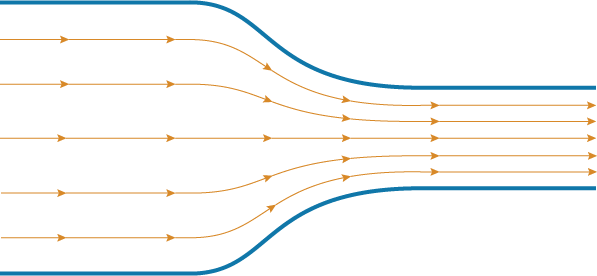

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build somgit e familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What is pressure?

Pressure is a measure of the force that a fluid exert on the wall of container. On a microscopic scale, the fluid particles are impacting the container wall and bounce back from it. Because the fluid is composed of a very large number of particle, all of those discrete impact can be added together over time. The resulting force from this very large number of impacts the pressure, often noted $p$ or $P$. Pressure is a scalar quatity that exist in the whole fluid domain, it is dimensionally equivalent to a force per unit of surface. The total resulting force on a surface can be calculated from the pressure by using the following formula:


$$F=P\times S$$


  **Try.** Run the following function to visualize fluid particle impact on a surface

 
plotPressure()

### Absolute vs. Relative pressure

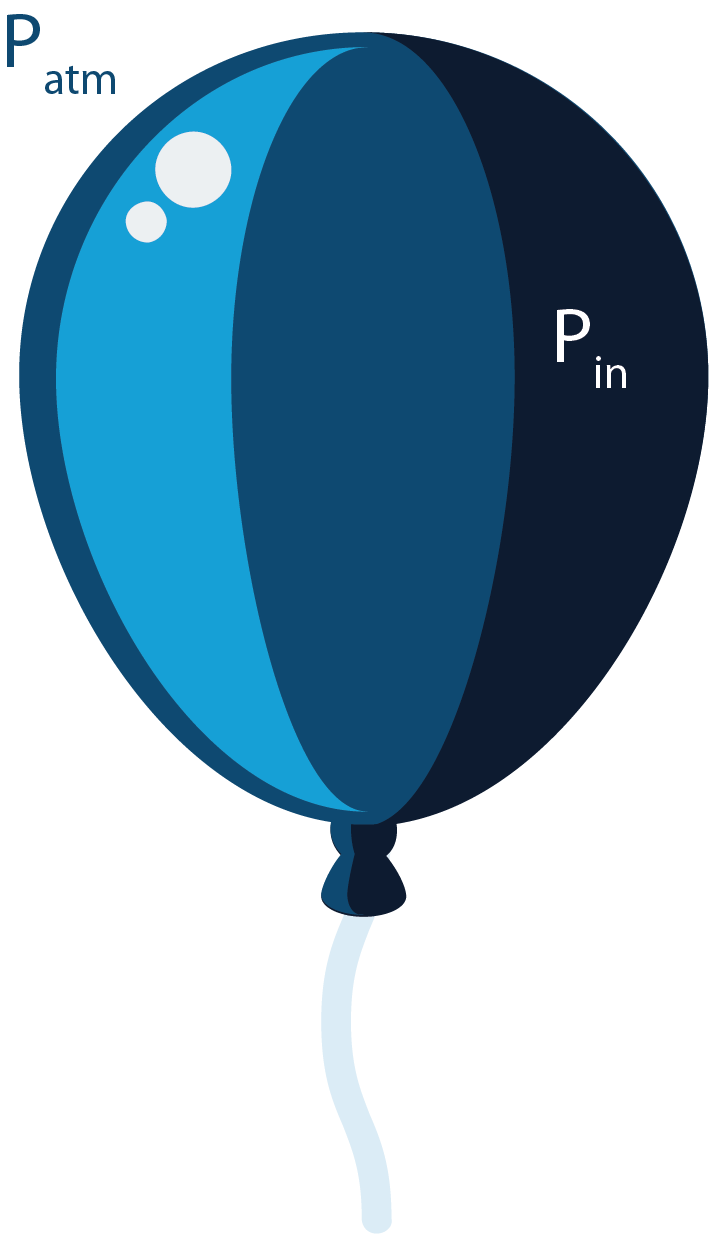

Take a party air balloon, the pressure inside the ballon $P_{in}$ is superior to the pressure outside the ballon $P_{atm}$, giving it its shape. There is three forces acting on the balloon:

- The atmospheric pressure exert a force toward the center of the balloon.

- The inner pressure exert a force from the center of the balloon outward.

- The surface tension of the rubber along the surface of the balloon.

The force in the balloon must balance each other, and therefore the surface tension force is function of the difference of pressure in between the inside and outside of the balloon. We define the relative pressure such that:


$$P_\text{relative}=P - P_\text{reference}$$


The pressure $P$ represents any pressure and is refered as absolute pressure so that:


$$P_\text{relative}=P_\text{absolute} - P_\text{reference}$$


The reference pressure is choosen to be the atmopsheric pressure so that the relative pressure of the atmosphere is zero and the relative pressure of the ballon is $P_{in} -P_{atm}$.

**Remark: **the most common reference pressure is the atmospheric pressure (1 atm = 101325 Pa), but we could use any arbitrary reference.

Pressure measurement are often relative pressure measurement, for example your bike tire pump will show a pressure of zero if your tire is completely deflated. It does not mean that the absolute pressure inside the tire is zero, but that the air inside the tire is at the same pressure then the atmosphere.

**Remark: **because the absolute pressure is a macroscopic measure of the fluid impact on a surface $P_\text{absolute} \geq 0$, there is either no impact or some impact, but negative number of impact does not make physical sense. However, because the relative pressure is an offset of pressure, negative relative pressure is possible.

### Units

The pressure reference unit in the standard unit system is the Pascal (Pa), named after the French mathematician and physicist [Blaise Pascal](https://en.wikipedia.org/wiki/Blaise_Pascal). However, engineers and scientist tends to use many different units depending on their field and application. While hydraulicist might use "meter of water" as unit of choice, aerodynamist might tend to use psi (pound per square inches) or Pa.

  **Try. **Run the following code to create a unit system and get information about Pascals.

units = symunit;
unitInfo(units.Pa)


pascal - a physical unit of pressure. ['SI']

Get all units for measuring 'Pressure' by calling unitInfo('Pressure').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



  **Try. **Following the prompt from `unitInfo`, explore all unit of pressure available

unitInfo("Pressure")


All units of dimension 'Pressure':

at - technical atmosphere
atm - standard atmosphere
Ba - barye 
bar - bar
cmH2O - centimeter of water (conventional)
cmHg - centimeter of mercury (conventional)
ftH2O - foot of water (conventional)
ftHg - foot of mercury (conventional)
inH2O - inch of water (conventional)
inHg - inch of mercury (conventional)
ksf - kip per square foot
ksi - kip per square inch
mH2O - meter of water (conventional)
mHg - meter of mercury (conventional)
mmH2O - millimeter of water (conventional)
mmHg - millimeter of mercury (conventional)
Pa - pascal ['SI']
psf - pound force per square foot
psi - pound force per square inch
pz - pieze
Torr - torr

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.


Some of the most common units of pressure are:

- mmHg (millimeter of mercury) is used in medicine to measure the blood pressure, for example a blood pressure of 120/80 means that the systolic (while the heart pump) pressure is 120 mmHg and the diastolic (while the heart is at rest in between beats) pressure is 80 mmHg.

- mH2O (meter of water) is used to design large hydraulic system such as pipeline or hydropower plant.

- atm (atmosphere) correspond to the atmospheric pressure at sea leavel (1 atm = 101325 Pa). It has been used in chemistry as standard pressure.

- bar (bar) closest multiple of Pascal to the atmosphere (1 bar = 100000 Pa), is now used to define the standard pressure in chemistry.

- psi/psf are commonly used in as empirical unit of pressure.

You should get familiar with some of the most common units that you might encounter in fluid mechanics: Pa, bar, atm and psi.

 **Exercise. **Use [`unitConversionFactor`](https://www.mathworks.com/help/symbolic/unitconversionfactor.html) to compute the conversion factor between bar to Pa, atm to Pa, bar to psi and atm to psi

bar2Pa = unitConversionFactor(units.Pa,units.Pa)
atm2Pa = unitConversionFactor(units.Pa,units.Pa)
bar2psi = unitConversionFactor(units.Pa,units.Pa)
atm2psi = unitConversionFactor(units.Pa,units.Pa)

 
checkUnitConversionFactor(bar2Pa, atm2Pa, bar2psi, atm2psi);

  **Try. E**xplore all unit of pressure availableFeel free to explore on your own more units such as mH2O and mmHg

% You can used this space to try computing any other pressure conversion factor:


So far, we learned about the different unit of pressure, how to define them and how to compute conversion factor from one unit to another. MATLAB is able to rewrite any symbolic expression expressed in one unit into an other compatible units. Two compatible units are units that are linked by a dimensionless conversion factor. For example, meter (m) and Farenheit (F) are two uncompatible units, while inch (in) and meter (m) are compatible units.

  **Try. E**xplore all unit of pressure availableFeel free to explore on your own more units such as mH2O and mmHg

inche = rewrite(units.in, units.m)

$$inche = 0.0254\,m$$

 **Exercise. **Use [`rewrite`](https://www.mathworks.com/help/symbolic/rewrite.html?searchHighlight=rewrite&s_tid=srchtitle_rewrite_1) to convert Pascals into Newton and meter.

pascals = 0

pascals = 0

 
checkDecompositionUnits(pascals);

 **Reflect**. Units of pressure such as Pascals correspond to Newton per square meter, wich correspond to unit of force per unit of surface.

## Bernoulli's Principle

### Definition

The Bernoulli equation is a fundamental equation of fluid dynamic that describes the relationship between pressure, velocity and elevation change in the fluid. This equation is named after the Swiss mathematician, Daniel Bernoulli, who first formulated it in 1738. The Bernoulli equation states that the total pressure of a fluid system is constant along a streamline:


$$P+
\frac{1}{2}\rho v^2+
\rho g z= \text{Constant} \qquad(\star)$$


where P represents the pressure of the fluid, $\rho$ its density, $v$ its velocity, $g$ gravitational acceleration and $z$ the elevation. The total pressure is defined as:


$$P_\text{total} = P + \frac{1}{2}\rho v^2 + \rho g z$$


- $P$ is the static pressure, as defined in the previous section. It can either be an absolute or relative pressure, **as long as the reference pressure is the same for all total pressure.**

- $\frac{1}{2}\rho v^2$ is the dynamic pressure, it is the pressure that is due to the bulk motion of the fluid.

- $\rho g h$ is the hydrostatic pressure, it is the pressure that is due to the gravitational potential. The component is really important in fluid system with liquid because of their high density and often neglected for fluid system with gas.

**Streamline: **In fluid dynamics, the mathematical definition of a streamline is the line in a flow that is tangent to the velocity vector at every point. Physically, it represents the path that a small, frictionless particle would follow if it were to flow in this fluid.

We should verify that each term of Bernoulli's equation is consistent with a unit of pressure.

  **Try. **Check if the dynamic pressure term is consistent as a unit of pressure.

units = symunit;
dynamicPressureUnits = units.kg/units.m^3*(units.m/units.s)^2;
checkUnits(dynamicPressureUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1

 **Exercise. **Similarly check that the hydrostatic pressure term is consistent as a unit of pressure.

% Your code goes in the next line:
hydrostaticPressureUnits = 0;

% Check the units consistency:
  checkUnits(hydrostaticPressureUnits == units.Pa)

ans = struct with fields:
    Consistent: 1
    Compatible: 1

 **Reflect**. Reflect on the similarity in between the term in equation $(\star)$ and the definition of work, kinetic energy and potential energy.

- Work: $W = \int P dV$

- Kinetic energy: $E_k = \frac{1}{2}mv^2$

- Potential energy: $E_p = mgz$

The Bernoulli equation $(\star)$ is often written in term of hydraulic head $H$:


$$\frac{P}{\rho g} + \frac{v^2}{2 g} + h = H_0=\text{Constant}
\quad\quad
(\spadesuit)$$


 **Exercise. **What is the unit of the different term in $(\spadesuit)$(hint: use [`simplify`](https://www.mathworks.com/help/symbolic/simplify.html) to simplify the expression)

% Your code goes in the next line:
hydraulicHeadUnit = 0;

% Symplify the unit expression
if hydraulicHeadUnit ~= 0
    hydraulicHeadUnit = simplify(hydraulicHeadUnit)
end

This form of the Bernoulli equation is commonly used in hydraulic network where the pressure drop due to a change of elevation a non-negligible.

### **Pressure along a streamline**

We are considering the streamline of a free-flowing fluid between point A and point B.The velocity at point A, point B and the elvation change is known. We will express the pressure in term of relative pressure, and the reference pressure is equal to the absolute pressure at point A, so that its relative pressure is 0. We are trying to compute the pressure at point B.

  **Try.** Use the slider below to visualize a streamline in between point A and point B of a fluid flow with an elevation difference.

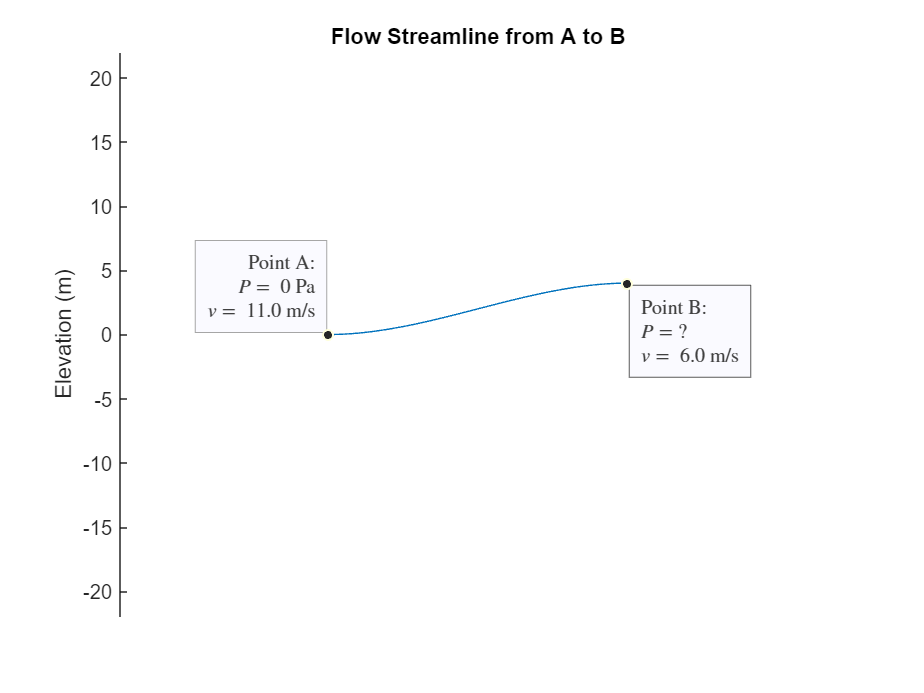

% Gather the user input:
changeElevation = 4;
downstreamVelocity = 6;
upstreamVelocity = 11;
density = 1000;

plotStreamline(changeElevation,upstreamVelocity,downstreamVelocity)

We are using the symbolic math toolbox to define the total pressure at point A and B as a function of the problem variable.

 **Exercise.** Write the total pressure at point A and point B.

% Define the variable:
syms pressureA pressureB velocityA velocityB g rho dh


% Your code goes here:
totalPressureA = 0;
totalPressureB = 0;

 checkFreeStreamBernoulli(totalPressureA,totalPressureB)

We can define the equality of the total pressure and solve for the pressure at point B.

  **Try. ** [Solve](https://www.mathworks.com/help/symbolic/sym.solve.html) the pressure at point B using equation $(\star)$.

% Define the equation to solve:
eqn = totalPressureB == totalPressureA;

% If the total pressure were defined in the previous exercise,
% substitute the known parameter in the equation:
if totalPressureA ~= 0 && totalPressureB ~= 0
    eqn = subs(eqn, [pressureA rho velocityA velocityB dh g], ...
        [0 density upstreamVelocity downstreamVelocity changeElevation 9.81])
end

% Solve for the downstream pressure:
downstreamPressure = solve(eqn, pressureB)*u.Pa;

$$downstreamPressure = 0$$

  **Try.** Rewrite the pressure in your unit of choice.

% Select your choise of pressure:
unitChoice = units.mH2O;

% Rewrite the upstream and downstream pressure in that unit:
downstreamPressure = rewrite(downstreamPressure, unitChoice) 

$$downstreamPressure = 0$$

### **Application: Converging Pipe Flow**

We just considered the flow along the streamline of a free-flowing fluid. In this section, we are consideing the flow in a convering pipe of upstram diameter $D_A$ and downstream diameter $D_B$, the inflow velocity is $V_A$ and the fluid is considered to be incompressible.

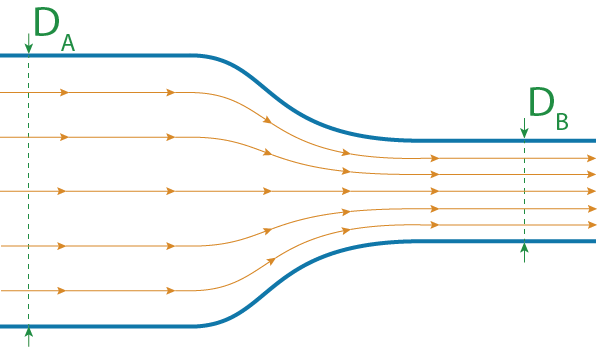

 **Exercise.** Considering that the mass is conserved in the pipe, express the velocity at point B as a function of the velocity at point A and the diameters.

% Define the problem parameters: 
syms diameterA diameterB velocityA pressureA pressureB rho

% You code goes here:
velocityB = 0;
  checkVelocityConvergentPipe(velocityB)

Following the same step then the previous section, we can express the total pressure at point A and B.

 **Exercise.** Express the total pressure at point A and B, considering no elevation change.

totalPressureA = 0;
totalPressureB = 0;

 checkTotalPressureConvergentPipe(totalPressureA, totalPressureB)

  **Try.** Solve the equation for $\Delta P = P_B - P_A$

pressureDifference = solve( totalPressureA == totalPressureB , pressureB ) - pressureA

$$pressureDifference = -\mathrm{pressureA}$$

pressureDifference = simplify(pressureDifference)

$$pressureDifference = -\mathrm{pressureA}$$

 **Reflect**. Knowing that $D_A > D_B$ should we expect the pressure to increase or decrease along the converging pipe? This counter-intuitive results is called Bernoulli's principle.

### **Application: Pitot tube**

A pitot tube is a device that is used to measure velocity with a fluid that is particularly used in aviation. It usually consist of a thin hollow tube pointed toward the fluid flow. For example, in the following figure, the A380's pitot tube is oriented toward to cockpit of the airplane. 

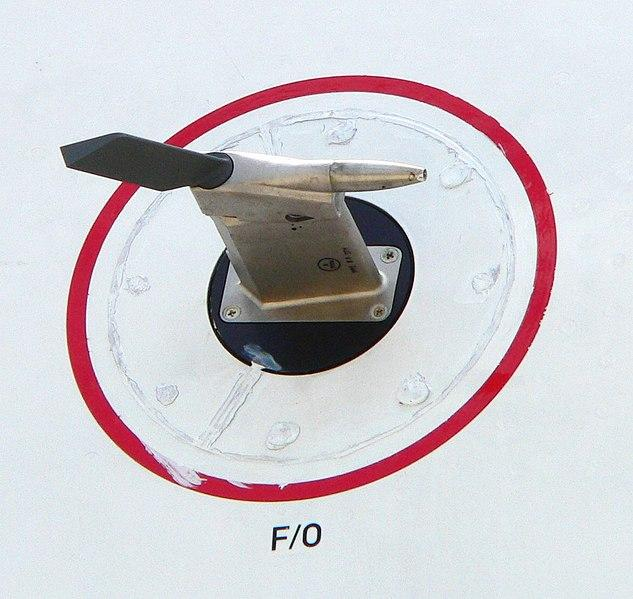

An Airbus A380's pitot tube, [wikimedia](https://commons.wikimedia.org/wiki/File:Airspeed_p1230157.jpg)

There is multiple type of Pitot tube, in this scripts we are studying a Pitot-static tube. This kind of device presents two opening, one in the front and one on the side. One of those opening is used to define the stagnation pressure:


$$P_\text{stagnation} = P_\text{static} + \frac{1}{2}\rho v^2 $$


This pressure represents the pressure that the fluid would have if it came to a sudden stop. The following figure presents a schematic representation of the Pitot-static tube with the pressure gauge that are considered here.

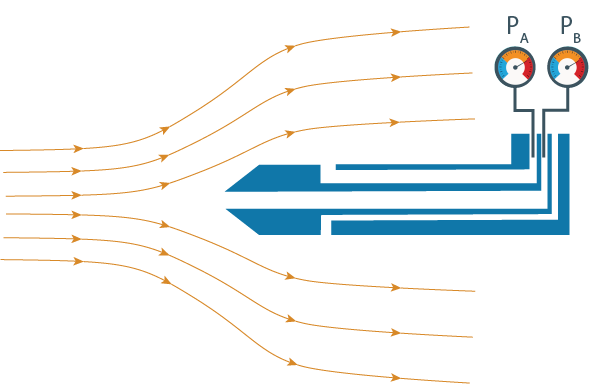

 **Exercise. **Identify the kind of pressure that is measured by each of the pressure gauge.

checkPressurePitot(GaugeA="None",GaugeB="None");
 

Now that both pressure are know, we are considering the difference of pressure between the two gauge: $\Delta P = P_B - P_A$

 **Exercise. **Based on your answer to the previous question, what pressure is equal to $\Delta P = P_B - P_A$ represents?

checkPressureDifferencePitot("None");

 **Exercise.** Express the free-stream velocity `freeStreamVelocity` as a function of $\Delta P= P_B - P_A$

% Declare the parameters of the problem:
syms staticPressure rho airVelocity

% Your code goes here:
pressureA = 0;
pressureB = 0;

% Compute the pressure difference:
pressureDifference = pressureB - pressureA
 checkPressureDiffPitot(pressureDifference)

  **Try.** Plot the pressure difference as a function of the air speed at a density of 1.14 kg/m-3 for airspeed from 0 to 100 m/s.

% Plot the results if the previous exercise was completed:
if pressureDifference ~= 0
    figure
    pressureDifference(airVelocity) = subs(pressureDifference, rho, 1.14);
    fplot(pressureDifference,[0 100],LineWidth=2)
    title("Static Pitot tube reading")
    ylabel("Pressure difference (Pa)")
    xlabel("Airpseed (m/s)")
end

### **Application: Lift generation around airfoil**

In this section we will be studying the lift generation around a NACA-2412 airfoil. The NACA airfoils are a series of wing profile developed by the National Advisory Committee for Aeronautics (NACA). The wing profile is defined by a series of digit representing physical characteristic of the airfoil. For example, the NACA-2412 has a max camber of **2**%, located at **4**0% of the chords, with a thickness of **12**% (**2412**).

[~,~,~] = NACA4digits(12,2,40);

For more information about NACA airfoil, please visit the documentation of the `NACA4digits` function available with this module.

We are going to sutdy the lift generated by this airfoil on a plane flying at a cruise speed of 120 kts, which is representative to small mono-propeller airplane such as the [Cessna-172](https://en.wikipedia.org/wiki/Cessna_172).

  **Try.** Define the problem parameters.

syms cruiseSpeed

The upstream velocity is considered to be equal to the atmospheric pressure (101325 Pa) and the air density is considered to be 1.14 kg/m3. 

downstreamPressure = 101325*units.Pa;
rhoAir = 1.14*units.kg/units.m^3;

  **Try.** Define the velocity along the upper and lower surface

upperVelocity = 94*units.m/units.s;
lowerVelocity = 80*units.m/units.s;

 **Exercise. **using Bernoulli's principle, compute the pressure along the upper and lower surface.

% Write your code here:
upperPressure = 0;
lowerPressure = 0;

if upperPressure ~= 0 && lowerPressure ~= 0 
    pressureDifference = simplify(upperPressure - lowerPressure)
end

  **Try. **Set a larger velocity along the lower surface than along the upper surfaces, 

 **Exercise. **Should the pressure difference be positive or negative to generate an upward "lift" force along the airfoil?

checkPressureDifferenceSign("None")

## Further Exploration

- In this script we only considered ideal flow where the total pressure is conserved along streamline. In all real flow, friction introduce pressure drop, therefore the total pressure decreases along streamline. These pressure loss, often called head losses, can be modelled. Explore [InternalFlow.mlx](matlab:open('./InternalFlow.mlx')) if you want to learn more about realistic flow applied to a house plumbing.

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

## Helper Functions

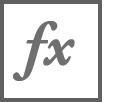**plotStreamline**`(dh, v1, v2, rho)`

- `dh `the elevation change along the streamline

- `v1 `the upstream velcity

- `v2 `the downstream velocity

- `rho` the fluid density

function plotStreamline(dh, v1, v2)
arguments
    dh (1,1) {mustBeReal,mustBeInRange(dh,-20,20)} = 0
    v1 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v1,0.0)} = 0.0
    v2 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v2,0.0)} = 0.0
end    

    % Define the path from A to B:
    xl = linspace(0,1,100);
    yl = -dh*(2*xl.^3-3*xl.^2);

    % Create the figure:
    figure
    ax = axes;
    
    % Plot A:
    s = scatter(ax,0,0,30,'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point A:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = $",  [0], "%10.0f Pa");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$v = $", [v1], "%10.1f m/s");
    d = datatip(s);
    d.Interpreter = "latex";
    d.Location = "northwest";
    hold on

    % Plot B:
    s = scatter(ax,1,dh, 'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point B:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = ?$",  [], "%10.0f Pa");
    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$v = $", [v2], "%10.1f m/s");
    d = datatip(s);
    d.Location = "southeast";
    d.Interpreter = "latex";
    
    
    % Plot Free Path:
    plot(ax,xl,yl)
    hold off

    % Set plot limit, title, etc.:
    xlim([-0.7 1.7])
    ylim([-22 22])
    title("Flow Streamline from A to B")
    ylabel("Elevation (m)")
    ax.XAxis.Visible = "off";
    
end

 `plotPressure()`

function plotPressure()
    % Create the figure and axis system
    figure;
    ax = axes;
    % Define the axis limit and disable its visibility
    axis off
    xlim(ax,[0 1.2])
    ylim(ax,[-1 1])
    % Draw the limit of the container as a plain thick line
    l = line(ax,[1 1],[-1 1],LineWidth=10);

    % Define the time step, initial position and velocity of the particles
    dt = 0.1;
    x = [0 2*rand-1];
    v = [1 2*rand-1] - x;
    v = v / norm(v);

    % Create the animated line and add the initial point
    h = animatedline(ax,MaximumNumPoints=7,LineWidth=4,Color=ax.ColorOrder(5,:));
    addpoints(h,x(1),x(2))

    % Perform 200 time step with particle bouncing back the wall
    for i = 1:200
        if l.Color == ax.ColorOrder(3,:)
            l.Color = ax.ColorOrder(1,:);
        end
        x = x + dt*v;
        if x(1) > 1.0
            x(1) = 1.0;
            v(1) = -v(1);
            l.Color = ax.ColorOrder(3,:);
        end
        if x(1) < 0.0
            x = [0 2*rand-1];
            v = [1 2*rand-1] - x;
            v = v / norm(v);
            clearpoints(h)
        end
        addpoints(h, x(1),x(2)) 
        drawnow
    end
    
end

`checkPressureDifferenceSign(answer)`

function checkPressureDifferenceSign(answer)
    arguments
        answer (1,1) string {mustBeMember(answer,{'None','Positive','Negative'})}
    end
    switch answer
        case "None"
            warning("Please select either positive or negative.")
        case "Positive"
            warning("XXX")
        case "Negative"
            disp("Good job! A negative pressure difference would create an force on the airfoil called lift.")
            [~,~,~] = NACA4digits(12,2,40);
            legend off
            annotation('arrow',[0.5 0.5],[0.5 0.7],LineWidth=3)
            annotation('textbox',[0.5 0.6 0.2 0.2],String="$\vec{F}$",Interpreter="latex",VerticalAlignment="bottom",LineStyle="none")
    end
end

`checkPressurePitot(opts)`

function checkPressurePitot(opts)
    arguments
        opts.GaugeA (1,1) string {mustBeMember(opts.GaugeA,{'None','Static','Stagnation','Absolute','Relative','Dynamic'})}
        opts.GaugeB (1,1) string {mustBeMember(opts.GaugeB,{'None','Static','Stagnation','Absolute','Relative','Dynamic'})}
    end

    if (opts.GaugeA == "Static" && opts.GaugeB == "Stagnation")
        disp("Good job! You have identified the pressure correctly.")
    elseif (opts.GaugeA == "Static")
        warning("You misidentified the pressure at gauge B, try again!")
    elseif (opts.GaugeB == "Stagnation")
        warning("You misidentified the pressure at gauge A, try again!")
    else
        warning("You misidentified both pressure, try again!")
    end

end

`checkPressureDifferencePitot(answer)`

function checkPressureDifferencePitot(answer)
    arguments
        answer (1,1) string {mustBeMember(answer,{'None','Static','Stagnation','Dynamic'})}
    end

    switch answer
        case "None"
            warning("Please select one of the options in the drop-down control.")
        case "Static"
            warning("The gauge A is already measuring the static pressure, so the difference between A and B can not be static pressure.")
        case "Stagnation"
            warning("The gauge B is already measuring the stagnation pressure, so the difference between A and B can not be static pressure.")
    end
    

    if answer == "Dynamic"
        disp("Good job! The pressure difference is the dynamic pressure.")
    end
end

`checkUnitConversionFactor(answerA,answerB,answerC,answerD)`

function checkUnitConversionFactor(answerA,answerB,answerC,answerD)
    arguments
        answerA (1,1) sym 
        answerB (1,1) sym
        answerC (1,1) sym
        answerD (1,1) sym
    end

    units = symunit;
    ibarPa  = isequal(answerA,unitConversionFactor(units.bar,units.Pa));
    iatmPa  = isequal(answerB,unitConversionFactor(units.atm,units.Pa));
    ibarpsi = isequal(answerC,unitConversionFactor(units.bar,units.psi));
    iatmpsi = isequal(answerD,unitConversionFactor(units.atm,units.psi));

    if ibarPa && iatmPa && ibarpsi && iatmpsi
        disp("Good job! You found the right convertion unit in between the atm, bar, Pa and psi.")
    else
        if ~ibarPa
            warning("The conversion factor between bar and Pa is wrong.")
        end
        if ~iatmPa
            warning("The conversion factor between atm and Pa is wrong.")
        end
        if ~ibarpsi
            warning("The conversion factor between bar and psi is wrong.")
        end
        if ~iatmpsi
            warning("The conversion factor between atm and psi is wrong.")
        end
        warning("Hint: To convert m and mm, you would use: unitConversionFactor(units.m,units.mm)")
    end
end

`checkDecompositionUnits(answer)`

function checkDecompositionUnits(answer)
    arguments
        answer (1,1) sym
    end
    
    units = symunit;
    if isequal(answer, rewrite(units.Pa, [units.m units.N]))
        disp("Good job! Pressure units are equivalent to unit of force per unit of surface.")
        disp("And Pascals is equivalent to Newton per square meter.")
    else
        warning("Hint: if you wanted to rewrite meter in millimeter, you would use rewrite(units.m, [units.mm])")
    end
end

`checkFreeStreamBernoulli(answerA,answerB)`

function checkFreeStreamBernoulli(answerA,answerB)
    arguments
        answerA (1,1) sym
        answerB (1,1) sym
    end

    syms pressureA pressureB rho velocityA velocityB g dh;
    tPA1 = pressureA + 0.5*rho*velocityA^2 + rho*g*0.0;
    tPB1 = pressureB + 0.5*rho*velocityB^2 + rho*g*dh;
    tPA2 = pressureB;
    tPB2 = pressureB + 0.5*rho*velocityB^2;
    tPB3 = pressureB + rho*g*dh;
    tPB4 = pressureB;

    if isequal(tPA1,answerA) && isequal(tPB1,answerB)
        disp("Good job! You defined both total pressure correctly.")
    end

    if isequal(answerA,tPA2)
        warning("You forgot the dynamic pressure in the total pressure at point A.")
    end

    if isequal(answerA,tPB2)
        warning("You forgot the difference of elevation in the total pressure at point B.")
    end
    if isequal(answerA,tPB3)
        warning("You forgot the dynamic pressure in the total pressure at point B.")
    end
    if isequal(answerA,tPB4)
        warning("You forgot the difference of elevation and the dynamic"+...
            " pressure in the total pressure at point B.")
    end

    if answerA == 0 && answerB == 0
        warning("Please, complete the line of codes defining the total pressure"+...
            " at point A and B.")
    end

end

`checkVelocityConvergentPipe(answer)`

function checkVelocityConvergentPipe(answer)
    arguments
        answer (1,1) sym
    end
    
    syms diameterA diameterB velocityA pressureA pressureB rho
    rightAnswer = (diameterA/diameterB)^2*velocityA;

    if isequal(answer,rightAnswer)
        disp("Good job! You expressed the velocity at point B correctly.")
    elseif answer == 0
        warning("Please complete line as indicated in the comment.")
    else
        warning("In this case, the conservation of mass impose the mass "+...
            "flow at point A to be equal to the mass flow at point B. A "+...
            "mass flow can be expressed as m_dot = rho*S*V.")
    end

 end

`checkTotalPressureConvergentPipe(answerA, answerB)`

function checkTotalPressureConvergentPipe(answerA, answerB)
    arguments
        answerA (1,1) sym
        answerB (1,1) sym
    end

    syms diameterA diameterB velocityA pressureA pressureB rho
    velocityB = (diameterA/diameterB)^2*velocityA; % Complete this line of code
    rightAnswerA = pressureA + 0.5*rho*velocityA^2;
    rightAnswerB = pressureB + 0.5*rho*velocityB^2;

    if isequal(answerA,rightAnswerA) && isequal(answerB,rightAnswerB)
        disp("Good job! You expressed both total pressure correctly.")
    else
        warning("Hint: it is the same expression as the one used previously for "+...
            "the free flow but wihtout a change in elevation.")
    end

end

`checkPressureDiffPitot(answer)`

function checkPressureDiffPitot(answer)
    arguments
        answer (1,1) sym
    end
    
    syms staticPressure rho airVelocity
    pressureA = staticPressure;
    pressureB = staticPressure + 0.5*rho*airVelocity^2;
    rightAnswer = pressureB - pressureA;

    if isequal(answer,rightAnswer)
        disp("Good job! You expressed the pressure difference correctly.")
    else
        warning("Hint: express the pressure at point A and B using the definition"+...
            " of the stagnation pressure. Then, compute pressureB - pressureA.")
    end
end

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

Copyright 2023 The MathWorks™, Inc